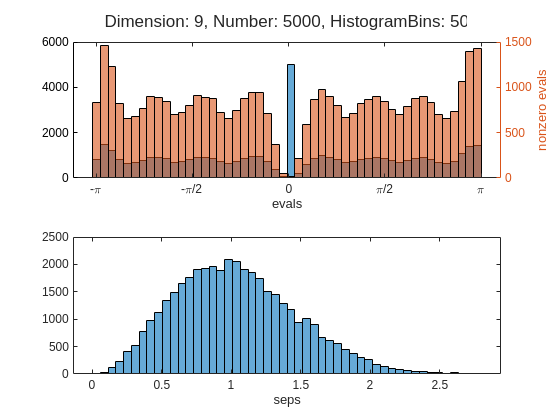

d = 9;      % dimension
n = 5000;   % samples
h = 50;     % histogram bins

evals = nan(d,n);
seps = nan(d-1,n);
dets = nan(1,n);

for ii = 1:n
    Q = sorthogonal(d, ii);
    dets(ii) = det(Q);
    [evals(:,ii), seps(:,ii)] = haarO(Q);
end
% evals = mod(evals(1:floor(d/2),:), pi/d); 

% evals and seps
figure; tl = tiledlayout('flow');
nexttile; 
histogram(evals,h,'Normalization','count'); xlabel('evals'); 
xticks([-pi:pi/2:pi]); xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
yyaxis right; histogram(nonzeros(evals),h,'Normalization','count'); ylabel('nonzero evals');
nexttile; 
histogram(seps,h,'Normalization','count'); xlabel('seps');
title(tl, sprintf("Dimension: %i, Number: %i, HistogramBins: %i", d, n, h));

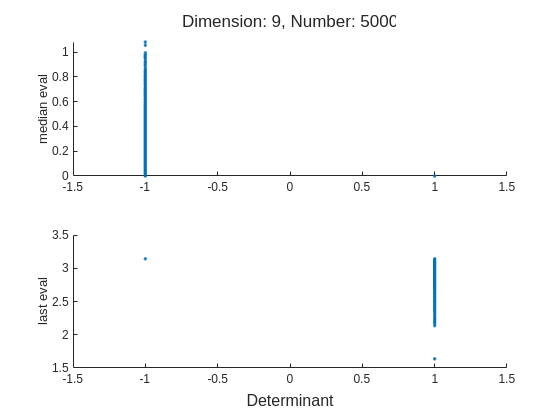

figure; tl = tiledlayout('flow'); 
nexttile; scatter(dets, evals(ceil(d/2),:), '.'); ylabel('median eval'); 
nexttile; scatter(dets, evals(end,:), '.');       ylabel('last eval'); 
title(tl, sprintf("Dimension: %i, Number: %i", d, n));
xlabel(tl, 'Determinant');

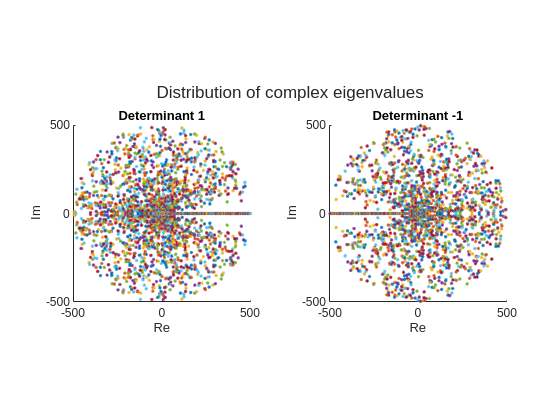


figure; tl = tiledlayout('flow'); 
for ii = 1:n/10
    nexttile(tl, (dets(ii)<0)+1);
    scatter(ii*cos(evals(:,ii)), ii*sin(evals(:,ii)), '.');
    hold on; axis square; xlabel('Re'); ylabel('Im'); 
end
title(nexttile(tl, 1), 'Determinant 1'); 
title(nexttile(tl, 2), 'Determinant -1');
title(tl, 'Distribution of complex eigenvalues'); 